clear 
close all
clc
%Podajemy nazwy 
Prompt={'XaRaster','YaRaster', 'XbRaster', 'YbRaster'};
        Title='Lokalizacja plików wejściowych';
          DefaultValues={'NDVI_1.tif', 'NDMI_1.tif', 'NDVI_2.tif','NDMI_2.tif'};
%Tworzy tablice            
PARAMS=inputdlg(Prompt,Title,[1 50; 1 50; 1 50; 1 50],DefaultValues);
XaRaster=imread(PARAMS{1});
YaRaster=imread(PARAMS{2});
XbRaster=imread(PARAMS{3});
YbRaster=imread(PARAMS{4});


% konwersja na liczby double
XaRaster=double(XaRaster);
YaRaster=double(YaRaster);
XbRaster=double(XbRaster);
YbRaster=double(YbRaster);

%Normalizacja
[hh,vv]=size(XaRaster);
for ii=1:hh
    for jj=1:vv
        if XaRaster(ii,jj)<0
            XaRaster(ii,jj)=0;
            YaRaster(ii,jj)=0;
            XbRaster(ii,jj)=0;
            YbRaster(ii,jj)=0;
        end
    end
end
pause(0.1);


## Delta

% DELTA
Xdelta=(XbRaster-XaRaster);
Ydelta=(YbRaster-YaRaster);
Xdelta2=((Xdelta).^2)

Xdelta2 =     0.0281    0.0240    0.0227    0.0132    0.0150    0.0104    0.0168    0.0335    0.0229    0.0195    0.0033    0.0209    0.0352    0.0112    0.0028    0.0102    0.0080    0.0270    0.0356    0.0266    0.0331    0.0007    0.0007    0.0001    0.0007    0.0001    0.0000    0.0002    0.0000    0.0000    0.0002    0.0014    0.0014    0.0004    0.0004    0.0006    0.0014    0.0039    0.0309    0.0147    0.0032    0.0004    0.0003    0.0017    0.0008    0.0053    0.0034    0.0058    0.0064    0.0006
    0.0348    0.0245    0.0234    0.0221    0.0236    0.0141    0.0189    0.0330    0.0162    0.0319    0.0269    0.0577    0.0646    0.0369    0.0307    0.0003    0.0005    0.0179    0.0182    0.0009    0.0015    0.0021    0.0029    0.0008    0.0023    0.0002    0.0009    0.0004    0.0002    0.0004    0.0004    0.0006    0.0007    0.0033    0.0026    0.0002    0.0032    0.0108    0.0220    0.0001    0.0002    0.0001    0.0007    0.0031    0.0033    0.0006    0.0014    0.0131    0.002

Ydelta2=((Ydelta).^2)

Ydelta2 =          0    0.0327    0.0383    0.0341    0.0289    0.0284    0.0224    0.0032    0.0267    0.0251    0.0762    0.0469    0.0422    0.0325    0.0111    0.0000    0.0166    0.0509    0.0271    0.0110    0.0002    0.0002    0.0000    0.0003    0.0001    0.0000    0.0002    0.0001    0.0003    0.0007    0.0003    0.0004    0.0004    0.0000    0.0001    0.0016    0.0008    0.0033    0.0023    0.0002    0.0006    0.0037    0.0064    0.0112    0.0117    0.0190    0.0208    0.0049    0.0087    0.0008
         0    0.0369    0.0408    0.0339    0.0333    0.0293    0.0435    0.0569    0.1310    0.0766    0.0850    0.0474    0.0466    0.0507    0.0416    0.0168    0.0000    0.0204    0.0088    0.0003    0.0002    0.0002    0.0000    0.0003    0.0000    0.0003    0.0002    0.0000    0.0000    0.0001    0.0003    0.0003    0.0003    0.0002    0.0002    0.0011    0.0002    0.0002    0.0060    0.0071    0.0068    0.0115    0.0048    0.0094    0.0121    0.0170    0.0110    0.0079    0.011

## Mapa zmian wielkości wektora

% Magnitude Map
MG=sqrt(Xdelta2+Ydelta2)

MG =     0.1677    0.2383    0.2469    0.2174    0.2096    0.1971    0.1979    0.1916    0.2227    0.2110    0.2819    0.2604    0.2781    0.2090    0.1181    0.1011    0.1569    0.2792    0.2504    0.1941    0.1824    0.0296    0.0272    0.0198    0.0273    0.0125    0.0152    0.0172    0.0167    0.0265    0.0226    0.0423    0.0420    0.0214    0.0208    0.0467    0.0463    0.0850    0.1823    0.1220    0.0616    0.0635    0.0819    0.1134    0.1117    0.1557    0.1558    0.1031    0.1227    0.0374
    0.1865    0.2479    0.2535    0.2366    0.2386    0.2082    0.2498    0.2999    0.3837    0.3294    0.3345    0.3243    0.3335    0.2959    0.2689    0.1306    0.0217    0.1957    0.1644    0.0349    0.0419    0.0487    0.0540    0.0332    0.0484    0.0223    0.0331    0.0197    0.0132    0.0228    0.0267    0.0294    0.0309    0.0597    0.0532    0.0362    0.0583    0.1046    0.1673    0.0845    0.0835    0.1077    0.0742    0.1116    0.1240    0.1326    0.1115    0.1451    0.1209    

MaxMG=max(max(MG))

MaxMG = 1.2775

MinMG=min(min(MG))

MinMG = 0

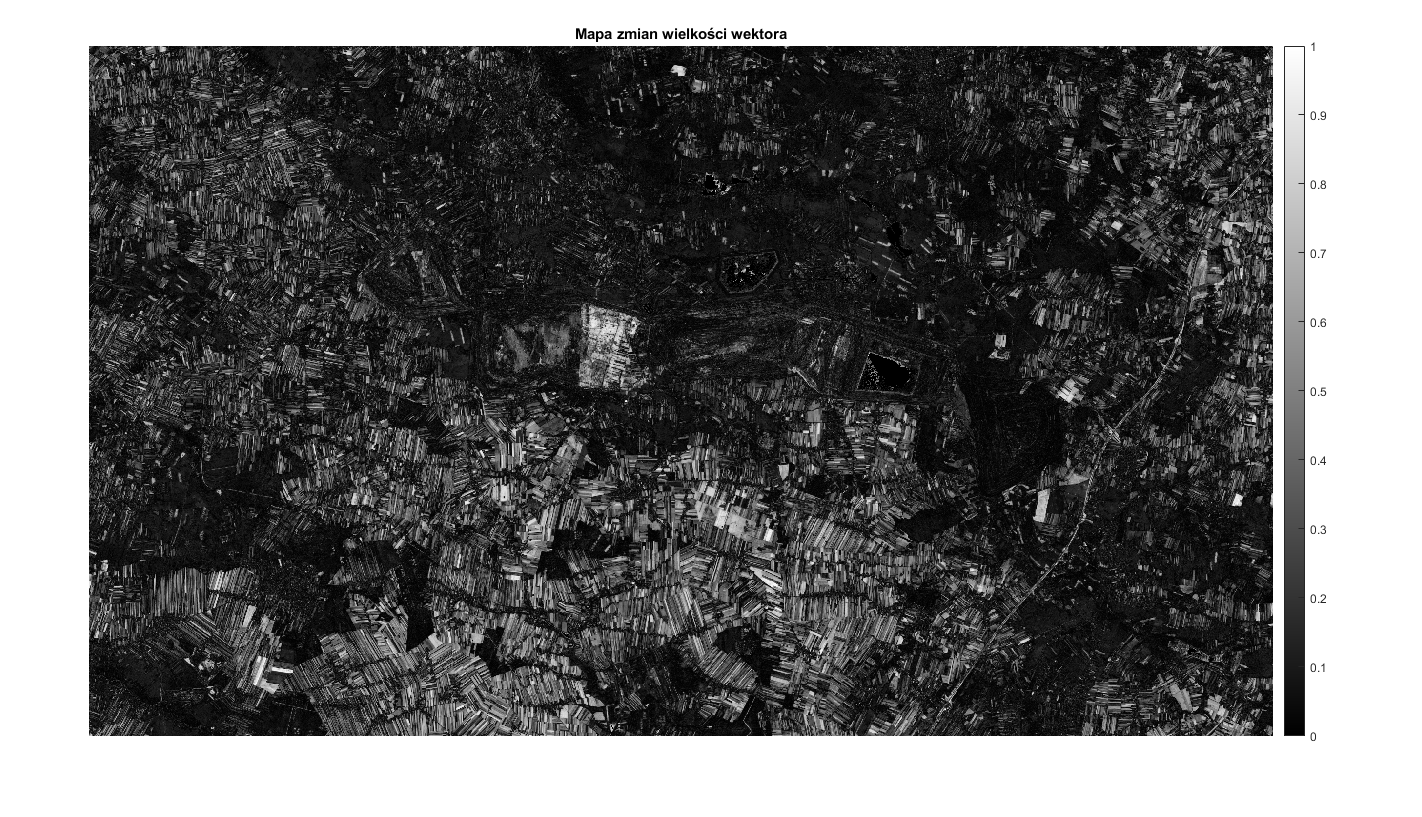

figure;imshow(MG)
title('Mapa zmian wielkości wektora')
colorbar
axis off
print('-djpeg','-r500','MagnitudeMap.jpg')

## Próg zmian

%Treshold
StandDevMG=std(std(MG))

StandDevMG = 0.0236

MeanMG=mean(mean(MG))

MeanMG = 0.1681

Treshold=MeanMG+StandDevMG

Treshold = 0.1917

%Change Map 
ChangeMap = (MG>Treshold)

ChangeMap = 2895×4968 logical array
   0   1   1   1   1   1   1   0   1   1   1   1   1   1   0   0   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   0   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   0   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

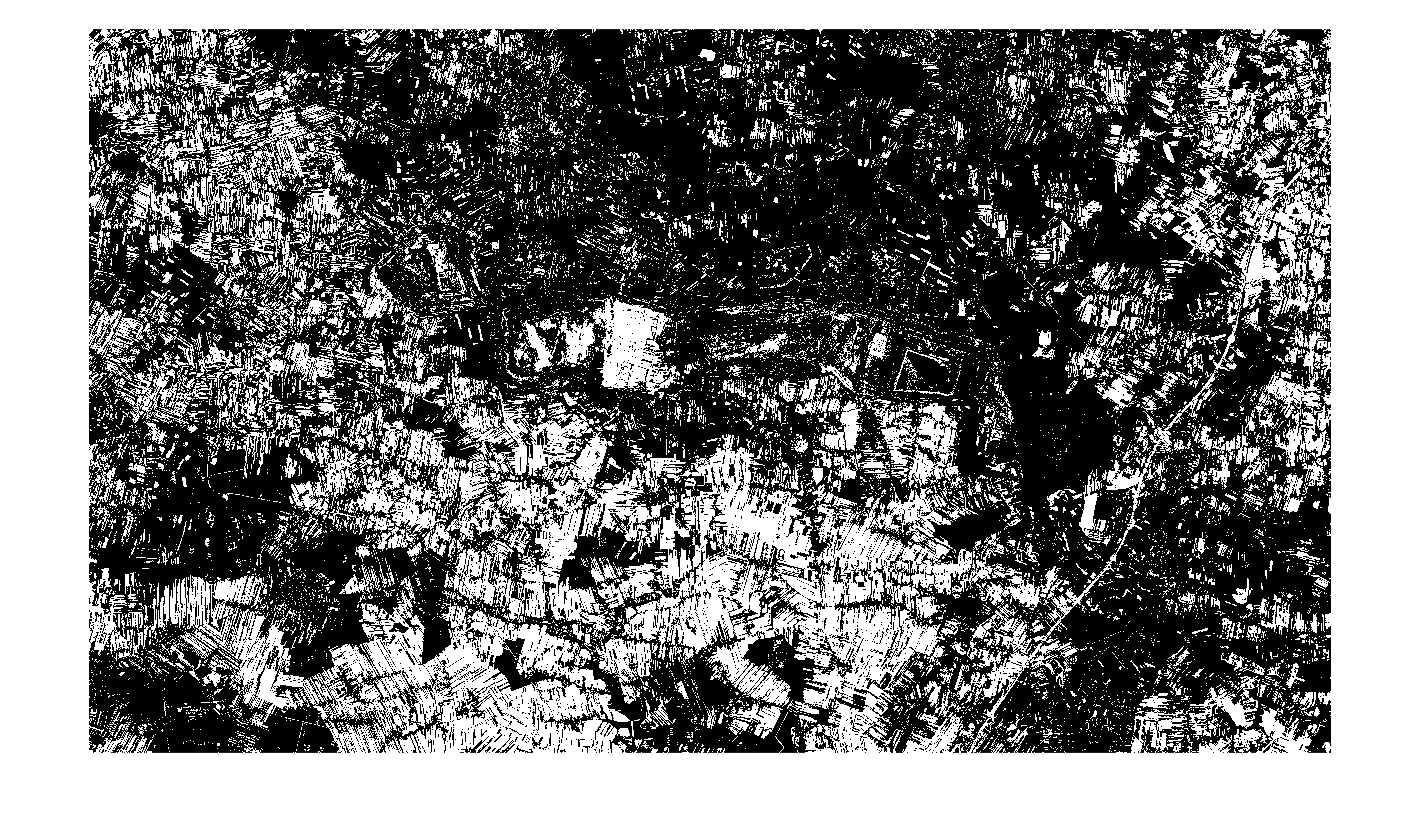

figure;imshow(ChangeMap)

## Kolor map

%Custom Map - klasy
map1 = [1.0 1.0 0.0
    0.6275 0.3216 0.1765
    0.0 0.0 1.0
    0.4863 0.9882 0];


## Mapa zmian kątów wektora

% Angle Map
AngleMap=(atand(Ydelta2./Xdelta2)).*4

AngleMap =          0  214.7674  237.3367  275.6936  250.2618  279.2403  212.7302   21.7675  197.4533  208.8168  350.1355  264.1020  200.5446  283.6638  302.8599    0.1372  257.4085  248.3423  149.1777   89.9329    1.2827   76.8020    0.3488  266.5025   29.2503   38.2766  341.1181  131.2747  354.6142  357.0736  203.0073   59.5829   55.8003    6.7415   40.1273  276.3238  118.1608  159.6278   16.9800    3.0514   40.7561  337.1040  348.4985  325.7455  344.6877  297.6760  322.5795  160.3790  215.1986  224.4992
         0  225.5770  240.7143  227.8672  218.7519  257.1926  266.2069  239.5994  331.8478  269.6414  289.6162  157.7244  143.2939  215.8756  214.5052  356.1635    2.5096  195.4131  103.5852   81.5671   31.8623   24.0793    3.8624   74.4729    3.8800  182.4042   40.4820   15.1356    5.6007   82.0906  151.4653  100.5577   83.6176   15.4302   20.5211  320.7258   12.2366    3.9483   60.4745  357.3798  352.5996  358.4531  326.1796  287.4855  298.7115  352.2903  331.0710  124.5968  307.89

MaxAngle=max(max(AngleMap))

MaxAngle = 360

MinAngle=(min(min(AngleMap)))

MinAngle = 0

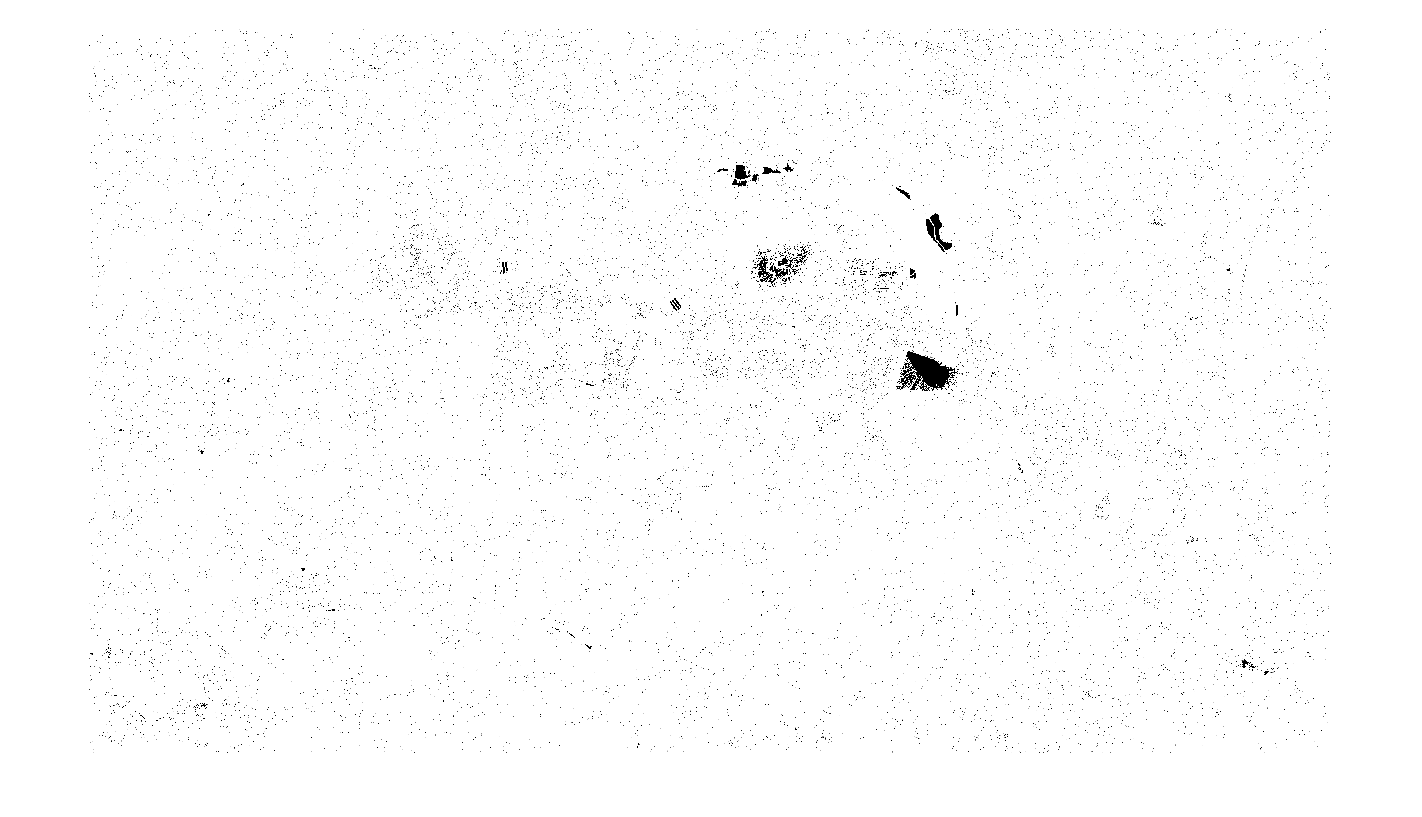

figure;imshow(AngleMap)

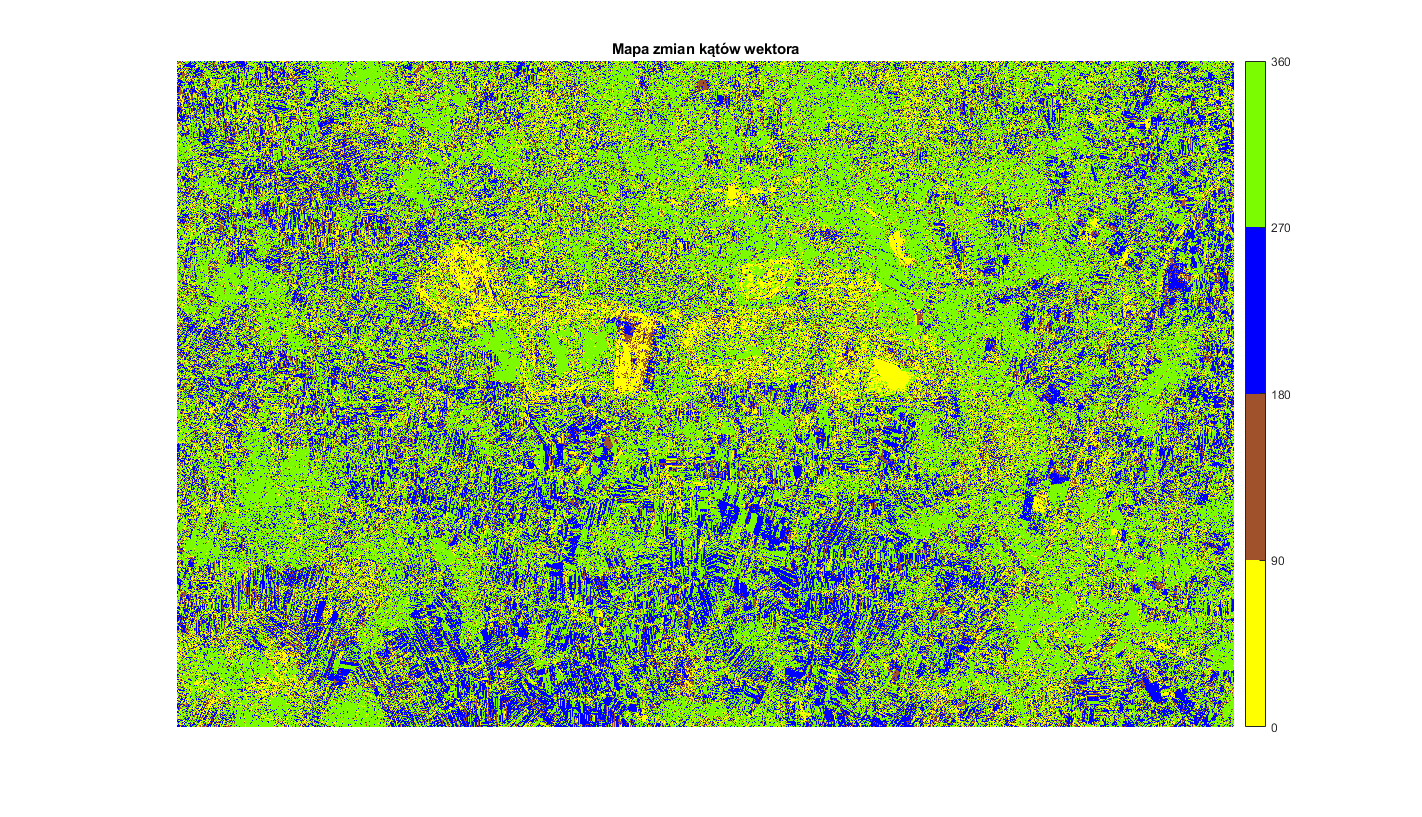

imagesc(AngleMap)
title("Mapa zmian kątów wektora")
colorbar('Ticks',[0 90 180 270 360],...
    'TickLabels',{'0','90','180','270','360'})
axis off
colormap(map1)
print('-djpeg','-r500','AngleMap.jpg')

## Ostateczna mapa zmiany

ChangeMap2=AngleMap./360

ChangeMap2 =          0    0.5966    0.6593    0.7658    0.6952    0.7757    0.5909    0.0605    0.5485    0.5800    0.9726    0.7336    0.5571    0.7880    0.8413    0.0004    0.7150    0.6898    0.4144    0.2498    0.0036    0.2133    0.0010    0.7403    0.0813    0.1063    0.9476    0.3647    0.9850    0.9919    0.5639    0.1655    0.1550    0.0187    0.1115    0.7676    0.3282    0.4434    0.0472    0.0085    0.1132    0.9364    0.9681    0.9048    0.9575    0.8269    0.8961    0.4455    0.5978    0.6236
         0    0.6266    0.6687    0.6330    0.6076    0.7144    0.7395    0.6656    0.9218    0.7490    0.8045    0.4381    0.3980    0.5997    0.5958    0.9893    0.0070    0.5428    0.2877    0.2266    0.0885    0.0669    0.0107    0.2069    0.0108    0.5067    0.1125    0.0420    0.0156    0.2280    0.4207    0.2793    0.2323    0.0429    0.0570    0.8909    0.0340    0.0110    0.1680    0.9927    0.9794    0.9957    0.9061    0.7986    0.8298    0.9786    0.9196    0.3461    0.

ChangeMap3=ChangeMap2.*ChangeMap

ChangeMap3 =          0    0.5966    0.6593    0.7658    0.6952    0.7757    0.5909         0    0.5485    0.5800    0.9726    0.7336    0.5571    0.7880         0         0         0    0.6898    0.4144    0.2498         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.6266    0.6687    0.6330    0.6076    0.7144    0.7395    0.6656    0.9218    0.7490    0.8045    0.4381    0.3980    0.5997    0.5958         0         0    0.5428         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

ChangeMap4=ChangeMap3.*360

ChangeMap4 =          0  214.7674  237.3367  275.6936  250.2618  279.2403  212.7302         0  197.4533  208.8168  350.1355  264.1020  200.5446  283.6638         0         0         0  248.3423  149.1777   89.9329         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0  225.5770  240.7143  227.8672  218.7519  257.1926  266.2069  239.5994  331.8478  269.6414  289.6162  157.7244  143.2939  215.8756  214.5052         0         0  195.4131         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

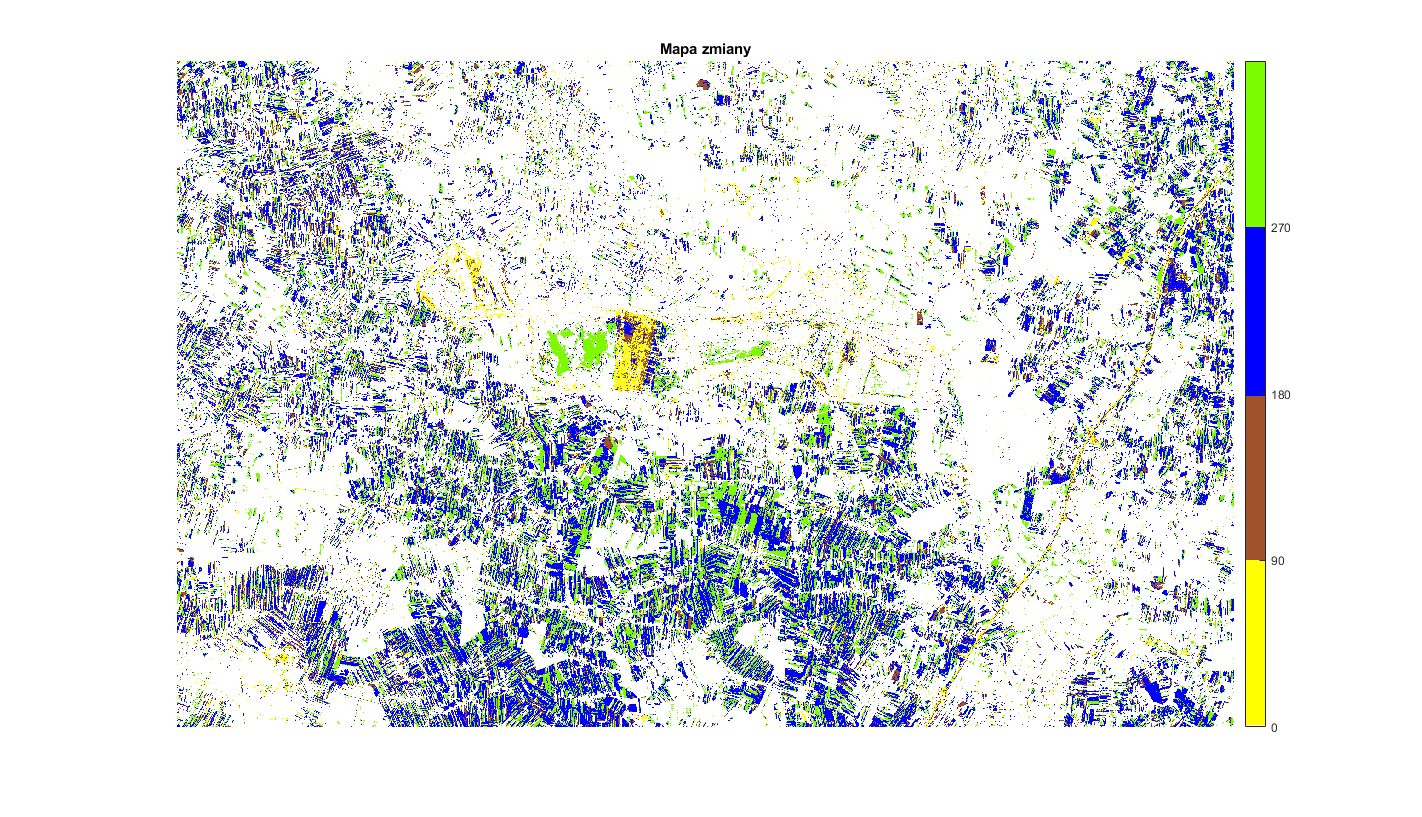

map3 = [1 1 1
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    1.0 1.0 0.0
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.6275 0.3216 0.1765
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
     0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
     0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
     0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
     0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
     0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
     0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
     0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
     0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.0 0.0 1.0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    0.4863 0.9882 0
    ];
imagesc(ChangeMap4)
colormap(map3)
title("Mapa zmiany")
colorbar('Ticks',[0 90 180 270 360],...
    'TickLabels',{'0','90','180','270','360'})
axis off
print('-djpeg','-r500','ChangeMap.jpg')


imtiff=geotiffinfo(PARAMS{1});
[A, R] = geotiffread(PARAMS{1}); 
mmm=imtiff.GeoTIFFCodes;
RRR=mmm.PCS;
geotiffwrite('ChangeMap.tif',ChangeMap4,R,'CoordRefSysCode',RRR)
[ChangeMap4, RR] = geotiffread('ChangeMap.tif');